# Decision trees

Your colleague has shared some training and testing data with you. You can assume the data has been properly prepared and split:

clear all;
load('split.mat', 'train_examples', 'train_labels', 'test_examples', 'test_labels');
rng(1);

Use the training data to train a decision tree using `fitctree()` (and without performing any merging or pruning of leaves) and answer the following questions:

- Use Matlab to generate a text-based description of your decision tree [2 marks]

- Use Matlab to generate a graphical description of your decision tree [1 marks]

- How many nodes are in your decision tree (answer in a short code comment)? [2 marks]

- How many of the nodes are leaf nodes (answer in a short code comment)? [2 marks]

- How many of the nodes are branch nodes (answer in a short code comment)? [2 marks]

- What class label does your tree predict for the eighth example (8th row) in the `test_exampes` table? [1 mark]

- What are the questions and answers generated by your tree in coming to this decision? [10 marks]

[Total: 20 marks]

% add as many lines of code as you need below:
m = fitctree(train_examples, train_labels) %train examples using fitctree() classifier, this returns the struct m

m =   ClassificationTree
           PredictorNames: {1×30 cell}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 427


  Properties, Methods


view(m) %call the view() function on m to return a text-based description of the decision tree generated by fitctree()

Decision tree for classification
 1  if area_worst<884.75 then node 2 elseif area_worst>=884.75 then node 3 else Benign
 2  if concavePoints_worst<0.1358 then node 4 elseif concavePoints_worst>=0.1358 then node 5 else Benign
 3  if concavity_mean<0.062425 then node 6 elseif concavity_mean>=0.062425 then node 7 else Malignant
 4  if radius_worst<16.805 then node 8 elseif radius_worst>=16.805 then node 9 else Benign
 5  if texture_mean<20.3 then node 10 elseif texture_mean>=20.3 then node 11 else Malignant
 6  if texture_mean<19.545 then node 12 elseif texture_mean>=19.545 then node 13 else Malignant
 7  class = Malignant
 8  if area_worst<785.75 then node 14 elseif area_worst>=785.75 then node 15 else Benign
 9  class = Benign
10  if area_worst<811.1 then node 16 elseif area_worst>=811.1 then node 17 else Benign
11  class = Malignant
12  class = Benign
13  class = Malignant
14  class = Benign
15  if radius_worst<16.215 then node 18 elseif radius_worst>=16.215 then node 19 else Benign
16

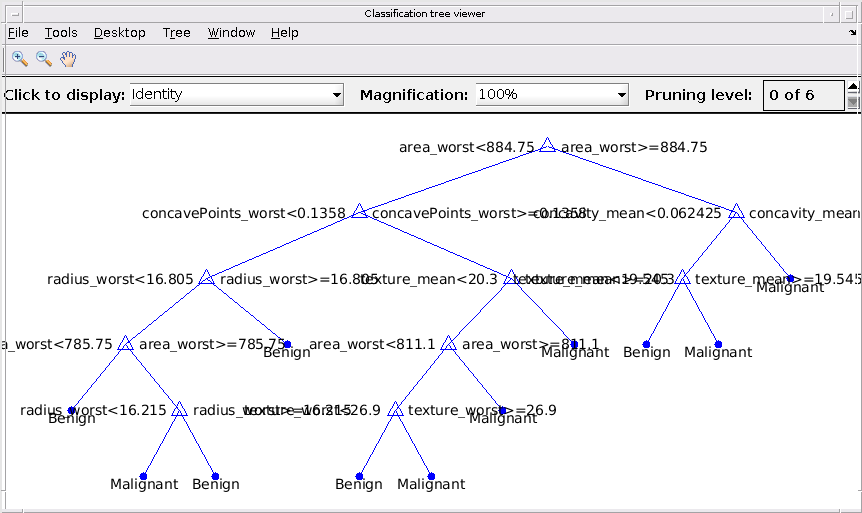


view(m, 'mode', 'graph') %%call the view() function on m (giving 'mode', 'graph' as parameters) to return a graphical description of the decision tree generated by fitctree()